A=[3,6,4;1,5,0;0,7,7]

A =      3     6     4
     1     5     0
     0     7     7


B=[1;2;3]

B =      1
     2
     3


x1=A\B

x1 =    -0.5824
    0.5165
   -0.0879


errorvector=A*x1-B

errorvector = 	1.0e+-15 *

   -0.1110
         0
         0



y1=@(l) l.*exp(-l/3);
i=quad(y1,0,5)

i = 4.4670

difference=i-(-24*exp(-5/3)+9)

difference = -2.0131e-09




plot(x,y,'b.',"MarkerSize",15)
hold on
[p1,s1,c1]=polyfit(x,y,1)

p1 =     0.0268    0.0383


s1 = struct with fields:
        R: [2×2 double]
       df: 48
    normr: 0.3840


c1 =   150.0000
   29.7498


[p2, s2, c2]=polyfit(x,y,2)

p2 =    -0.0209    0.0268    0.0589


s2 = struct with fields:
        R: [3×3 double]
       df: 47
    normr: 0.3614


c2 =   150.0000
   29.7498


[p3,s3,c3]=polyfit(x,y,3)

p3 =    -0.0216   -0.0209    0.0648    0.0589


s3 = struct with fields:
        R: [4×4 double]
       df: 46
    normr: 0.3423


c3 =   150.0000
   29.7498


[p4,s4,c4]=polyfit(x,y,4)

p4 =    -0.0161   -0.0216    0.0195    0.0648    0.0470


s4 = struct with fields:
        R: [5×5 double]
       df: 45
    normr: 0.3341


c4 =   150.0000
   29.7498


[p5,s5,c5]=polyfit(x,y,5)

p5 =     0.0777   -0.0161   -0.2749    0.0195    0.2240    0.0470


s5 = struct with fields:
        R: [6×6 double]
       df: 44
    normr: 0.1276


c5 =   150.0000
   29.7498


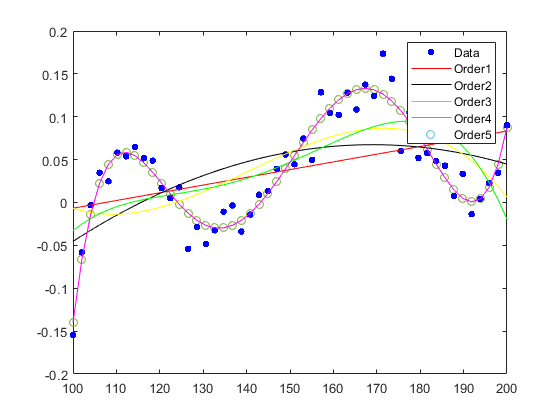

plot(x,polyval(p1,x,s1,c1),'r')
hold on
plot(x,polyval(p2,x,s2,c2),'k')
hold on
plot(x,polyval(p3,x,s3,c3),'y')
hold on
plot(x,polyval(p4,x,s4,c4),'g')
hold on
plot(x,polyval(p5,x,s5,c5),'m')
hold on
legend('Data','Order1','Order2','Order3','Order4','Order5')